ng = 5

ng = 5

ns = 11

ns = 11

[M,r,beta,L,alfa] = PS_PRJ_1_Faza_1(ng,ns)

M = 29

r = 90

beta = 6

L = 7

alfa = 50

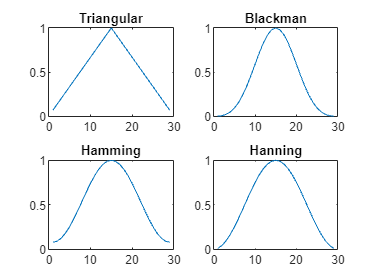


M = 29;
r = 90;
beta = 6;
L = 7;
alfa = 50;

%a.
dr = boxcar(M);
tr = triang(M);
blm = blackman(M);
ham = hamming(M);
han = hanning(M);
cheb = chebwin(M,r);
chebm5 = chebwin(M,r-5);
chebp5 = chebwin(M,r+5);
ksr = kaiser(M,beta);
ksrm1 = kaiser(M,beta-1);
ksrp1 = kaiser(M,beta+1);
tuc = tukeywin(M,alfa/100);
tucm15 = tukeywin(M,(alfa-15)/100);
tucp15 = tukeywin(M,(alfa+15)/100);
lan = lanczos(M,L);
lanm1 = lanczos(M,L-1);
lanp1 = lanczos(M,L+1);

%Figura 1
figure;
subplot(2,2,1);
plot(tr);
title('Triangular');

subplot(2,2,2);
plot(blm);
title('Blackman');

subplot(2,2,3);
plot(ham);
title('Hamming');

subplot(2,2,4);
plot(han);
title('Hanning');

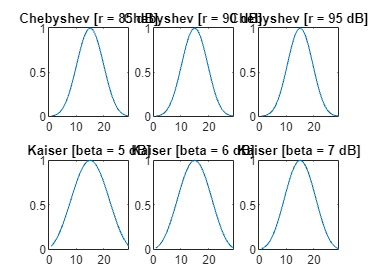


%Figura 2
figure;
subplot(2,3,1);
plot(chebm5);
title('Chebyshev [r = 85 dB]');

subplot(2,3,2);
plot(cheb);
title('Chebyshev [r = 90 dB]');

subplot(2,3,3);
plot(chebp5);
title('Chebyshev [r = 95 dB]');

subplot(2,3,4);
plot(ksrm1);
title('Kaiser [beta = 5 dB]');

subplot(2,3,5);
plot(ksr);
title('Kaiser [beta = 6 dB]');

subplot(2,3,6);
plot(ksrp1);
title('Kaiser [beta = 7 dB]');

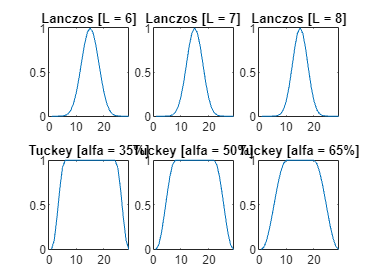


%Figura 3
figure;
subplot(2,3,1);
plot(lanm1);
title('Lanczos [L = 6]');

subplot(2,3,2);
plot(lan);
title('Lanczos [L = 7]');

subplot(2,3,3);
plot(lanp1);
title('Lanczos [L = 8]');

subplot(2,3,4);
plot(tucm15);
title('Tuckey [alfa = 35%]');

subplot(2,3,5);
plot(tuc);
title('Tuckey [alfa = 50%]');

subplot(2,3,6);
plot(tucp15);
title('Tuckey [alfa = 65%]');

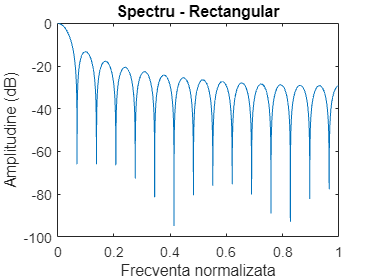


%b.
K = 5000;
dr = dr/sum(dr);
tr = tr/sum(tr);
blm = blm/sum(blm);
ham = ham/sum(ham);
han = han/sum(han);
cheb = cheb/sum(cheb);
chebm5 = chebm5/sum(chebm5);
chebp5 = chebp5/sum(chebp5);
ksr = ksr/sum(ksr);
ksrm1 = ksrm1/sum(ksrm1);
ksrp1 = ksrp1/sum(ksrp1);
tuc = tuc/sum(tuc);
tucm15 = tucm15/sum(tucm15);
tucp15 = tucp15/sum(tucp15);
lan = lan/sum(lan);
lanm1 = lanm1/sum(lanm1);
lanp1 = lanp1/sum(lanp1);

[h_dr,w_dr] = freqz(dr,1,K);
[h_tr,w_tr] = freqz(tr,1,K);
[h_blm,w_blm] = freqz(blm,1,K);
[h_ham,w_ham] = freqz(ham,1,K);
[h_han,w_han] = freqz(han,1,K);
[h_cheb,w_cheb] = freqz(cheb,1,K);
[h_chebm5,w_chebm5] = freqz(chebm5,1,K);
[h_chebp5,w_chebp5] = freqz(chebp5,1,K);
[h_ksr,w_ksr] = freqz(ksr,1,K);
[h_ksrm1,w_ksrm1] = freqz(ksrm1,1,K);
[h_ksrp1,w_ksrp1] = freqz(ksrp1,1,K);
[h_tuc,w_tuc] = freqz(tuc,1,K);
[h_tucm15,w_tucm15] = freqz(tucm15,1,K);
[h_tucp15,w_tucp15] = freqz(tucp15,1,K);
[h_lan,w_lan] = freqz(lan,1,K);
[h_lanm1,w_lanm1] = freqz(lanm1,1,K);
[h_lanp1,w_lanp1] = freqz(lanp1,1,K);

%Figura 4
figure;
subplot(1,1,1);
plot(w_dr/pi,20*log10(abs(h_dr)));
title('Spectru - Rectangular');
xlabel('Frecventa normalizata');
ylabel('Amplitudine (dB)');

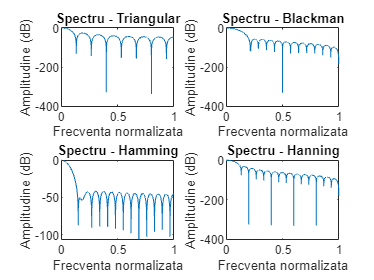


%Figura 5
figure;
subplot(2,2,1);
plot(w_tr/pi,20*log10(abs(h_tr)));
title('Spectru - Triangular');
xlabel('Frecventa normalizata');
ylabel('Amplitudine (dB)');

subplot(2,2,2);
plot(w_blm/pi,20*log10(abs(h_blm)));
title('Spectru - Blackman');
xlabel('Frecventa normalizata');
ylabel('Amplitudine (dB)');

subplot(2,2,3);
plot(w_ham/pi,20*log10(abs(h_ham)));
title('Spectru - Hamming');
xlabel('Frecventa normalizata');
ylabel('Amplitudine (dB)');

subplot(2,2,4);
plot(w_han/pi,20*log10(abs(h_han)));
title('Spectru - Hanning');
xlabel('Frecventa normalizata');
ylabel('Amplitudine (dB)');

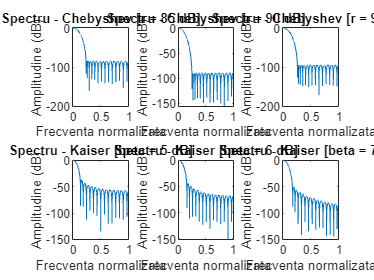


%Figura 6
figure;
subplot(2,3,1);
plot(w_chebm5/pi,20*log10(abs(h_chebm5)));
title('Spectru - Chebyshev [r = 85 dB]');
xlabel('Frecventa normalizata');
ylabel('Amplitudine (dB)');

subplot(2,3,2);
plot(w_cheb/pi,20*log10(abs(h_cheb)));
title('Spectru - Chebyshev [r = 90 dB]');
xlabel('Frecventa normalizata');
ylabel('Amplitudine (dB)');

subplot(2,3,3);
plot(w_chebp5/pi,20*log10(abs(h_chebp5)));
title('Spectru - Chebyshev [r = 95 dB]');
xlabel('Frecventa normalizata');
ylabel('Amplitudine (dB)');

subplot(2,3,4);
plot(w_ksrm1/pi,20*log10(abs(h_ksrm1)));
title('Spectru - Kaiser [beta = 5 dB]');
xlabel('Frecventa normalizata');
ylabel('Amplitudine (dB)');

subplot(2,3,5);
plot(w_ksr/pi,20*log10(abs(h_ksr)));
title('Spectru - Kaiser [beta = 6 dB]');
xlabel('Frecventa normalizata');
ylabel('Amplitudine (dB)');

subplot(2,3,6);
plot(w_ksrp1/pi,20*log10(abs(h_ksrp1)));
title('Spectru - Kaiser [beta = 7 dB]');
xlabel('Frecventa normalizata');
ylabel('Amplitudine (dB)');

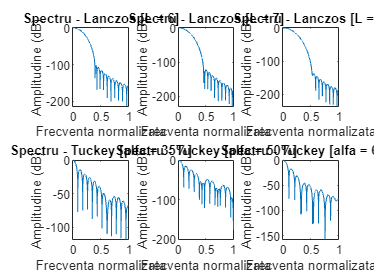


%Figura 7
figure;
subplot(2,3,1);
plot(w_lanm1/pi,20*log10(abs(h_lanm1)));
title('Spectru - Lanczos [L = 6]');
xlabel('Frecventa normalizata');
ylabel('Amplitudine (dB)');

subplot(2,3,2);
plot(w_lan/pi,20*log10(abs(h_lan)));
title('Spectru - Lanczos [L = 7]');
xlabel('Frecventa normalizata');
ylabel('Amplitudine (dB)');

subplot(2,3,3);
plot(w_lanp1/pi,20*log10(abs(h_lanp1)));
title('Spectru - Lanczos [L = 8]');
xlabel('Frecventa normalizata');
ylabel('Amplitudine (dB)');

subplot(2,3,4);
plot(w_tucm15/pi,20*log10(abs(h_tucm15)));
title('Spectru - Tuckey [alfa = 35%]');
xlabel('Frecventa normalizata');
ylabel('Amplitudine (dB)');

subplot(2,3,5);
plot(w_tuc/pi,20*log10(abs(h_tuc)));
title('Spectru - Tuckey [alfa = 50%]');
xlabel('Frecventa normalizata');
ylabel('Amplitudine (dB)');

subplot(2,3,6);
plot(w_tucp15/pi,20*log10(abs(h_tucp15)));
title('Spectru - Tuckey [alfa = 65%]');
xlabel('Frecventa normalizata');
ylabel('Amplitudine (dB)');

function lan = lanczos(M,L)
    n = 0:M-1;
    lan = sinc(((2*n)/(M-1))-1).^L;
end

function [M,r,beta,L,alfa] = PS_PRJ_1_Faza_1(ng,ns) 

% Constante
% ~~~~~~~~~
   ng_min = 1 ; % 333AB
   ng_max = 8 ; % Restantieri
   ns_min = 1 ; % numarul primului student in grupa
   ns_max = 30 ; % dimensiunea maxima a grupei
   r_min = 80 ; 
   r_max = 100 ; 
   beta_min = 2 ; 
   beta_max = 10 ; 
   alfa_min = 20 ; 
   alfa_max = 80 ; 
   rng = ng_max/ng_min ; 
   rns = ns_max/ns_min ; 
%
% Parametri specifici
% ~~~~~~~~~~~~~~~~~~~
   N_min = 30 ; 
   N_max = 400 ; 
   rN = N_max/N_min ;
   if ((rng <= rN) && (rN <= rns))
      delta = ng_min*ns_max-ng_max*ns_min ;
      a = ns_max*N_min-ns_min*N_max ;
      b = ng_min*N_max-ng_max*N_min ;
   elseif (rN > rns)
      delta = ng_max*ns_max-ng_min*ns_min ;
      a = ns_max*N_min-ns_min*N_max ;
      b = ng_max*N_max-ng_min*N_min ; 
   else
      delta = ng_min*ns_min-ng_max*ns_max ; 
      a = ns_min*N_min-ns_max*N_max ; 
      b = ng_min*N_max-ng_max*N_min ; 
   end
%
% Evaluare si normalizare suprafata de intregi
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
   [NG,NS] = meshgrid(ng_min:ng_max,ns_min:ns_max) ; 
   N = round((a*NG+b*NS)/delta) ;
   N = (N'-N_min)/(N_max-N_min) ;
%
% Generare matrice de amestecare
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
%   L = [] ;
%   for ng=ng_min:ng_max
%      L = [L randperm(ns_max)'] ;
%   end ; 
   L = [12    29    20    11    30    25     6    19
        10    11    25     9    27    13     2    17
        25     1    21    19    23    10     9    15
         1     4     3    27     7    11    25     5
         5    13    27    20    28     2    21    10
         3    15    19     6     4    21     1    24
        13     8    28    14    15    19    27     3
        19    24    22    29    13     7    20    21
        24    18     6     7    10    12    28    23
        17     3    23    12    24     5    30    20
        29    25    24    28    14    23    12    18
         6    12     5     8    18     4    24    28
        30    19     7    23     5    14    26    13
        11    23     8     5    26    30    15     7
        14    22    11    26     6    17     3     4
         9    10    12     4    25    24     8    22
        26     9    17     2     1    22    18     8
        18    30     1    22     8     6    17     2
        16    20     2    24    19     9    22    30
         3    26    13    15     9    16     4     1
         4    14    26    16     2     3    11     9
         7    28     9    25    22     8    14    16
        22     6    10    13     3    26     7    29
        27    17    29    10    12    15    19     6
        28    21    14    17    16    27     5    11
         8     7    16    21    17     1    29    25
        15    27     4    30    21    18    16    12
         2    16    18     1    29    20    23    14
        20     5    30    18    11    28    10    26
        21     2    15     3    20    29    13    27]' ;
%
% Amestecare matrice de intregi
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
   for r=ng_min:ng_max
      N(r,:) = N(r,L(r,:)) ;
   end
   N = N(ng,ns) ;
%
% Generare M
% ~~~~~~~~~~
   M = L(ng,ns) + 15 ; 
%
% Generare r
% ~~~~~~~~~~
   r = r_min + N*(r_max-r_min) ;
%
% Generare beta
% ~~~~~~~~~~~~~~
   beta = beta_min + N*(beta_max-beta_min) ;
%
% Generare L
% ~~~~~~~~~~
   L = rem(M,6) + 2 ;
%
% Generare alfa
% ~~~~~~~~~~~~~~
   alfa = alfa_min + N*(alfa_max-alfa_min) ;
end